clear all
syms P1 P2 v1 v2 rho D1 D2;

DP=P2-P1;

S1=(D1/2)^2*pi;
S2=(D2/2)^2*pi;
eqn1=S1*v1*rho==S2*v2*rho;
eqn2=P1+0.5*rho*v1^2==P2+0.5*rho*v2^2;
v2_=solve(eqn1,v2)

$$v2\_ = \frac{{D_{1}}^{2}\,v_{1}}{{D_{2}}^{2}}$$

eqn2=subs(eqn2,v2,v2_)

$$eqn2 = \frac{\rho \,{v_{1}}^{2}}{2}+P_{1}=P_{2}+\frac{{D_{1}}^{4}\,\rho \,{v_{1}}^{2}}{2\,{D_{2}}^{4}}$$

v1_=solve(eqn2,v1);
v1_=v1_(1)

$$v1\_ = \frac{\sqrt{2}\,{D_{2}}^{2}\,\sqrt{\rho \,\left(D_{1}-D_{2}\right)\,\left(P_{1}-P_{2}\right)\,\left({D_{1}}^{2}+{D_{2}}^{2}\right)\,\left(D_{1}+D_{2}\right)}}{{D_{1}}^{4}\,\rho -{D_{2}}^{4}\,\rho }$$

v1_=simplify(v1_)

$$v1\_ = \frac{\sqrt{2}\,{D_{2}}^{2}\,\left(P_{1}-P_{2}\right)}{\sqrt{\rho \,\left(D_{1}-D_{2}\right)\,\left(P_{1}-P_{2}\right)\,\left({D_{1}}^{2}+{D_{2}}^{2}\right)\,\left(D_{1}+D_{2}\right)}}$$

latex(v1_)

ans = '\frac{\sqrt{2}\,{D_{2}}^2\,\left(P_{1}-P_{2}\right)}{\sqrt{\rho \,\left(D_{1}-D_{2}\right)\,\left(P_{1}-P_{2}\right)\,\left({D_{1}}^2+{D_{2}}^2\right)\,\left(D_{1}+D_{2}\right)}}'

## plot

syms DP
rho=997;%kg/m^3
D1=20e-3;
D2=10e-3;
S1=(D1/2)^2*pi;
S2=(D2/2)^2*pi;
eqn1=S1*v1*rho==S2*v2*rho;
eqn2=P1+0.5*rho*v1^2==P2+0.5*rho*v2^2;
v2_=solve(eqn1,v2)

$$v2\_ = 4\,v_{1}$$

eqn2=subs(eqn2,v2,v2_)

$$eqn2 = \frac{997\,{v_{1}}^{2}}{2}+P_{1}=7976\,{v_{1}}^{2}+P_{2}$$

v1_=solve(eqn2,v1);
v1_=v1_(1)

$$v1\_ = -\frac{\sqrt{2}\,\sqrt{14955}\,\sqrt{P_{1}-P_{2}}}{14955}$$

latex(simplify(v1_))

ans = '-\frac{\sqrt{29910}\,\sqrt{P_{1}-P_{2}}}{14955}'

V1=subs(v1_,P2-P1,DP)

$$V1 = -\frac{\sqrt{2}\,\sqrt{14955}\,\sqrt{-\mathrm{DP}}}{14955}$$

DP_=solve(v1==V1,DP)

$$DP\_ = -\frac{14955\,{v_{1}}^{2}}{2}$$

v_ = 0:0.1:3;

DP_calc = subs(DP_,v1,v_)

$$DP\_calc = \left(\begin{array}{ccccccccccccccccccccccccccccccc} 0 & -\frac{2991}{40} & -\frac{2991}{10} & -\frac{26919}{40} & -\frac{5982}{5} & -\frac{14955}{8} & -\frac{26919}{10} & -\frac{146559}{40} & -\frac{23928}{5} & -\frac{242271}{40} & -\frac{14955}{2} & -\frac{361911}{40} & -\frac{53838}{5} & -\frac{505479}{40} & -\frac{146559}{10} & -\frac{134595}{8} & -\frac{95712}{5} & -\frac{864399}{40} & -\frac{242271}{10} & -\frac{1079751}{40} & -29910 & -\frac{1319031}{40} & -\frac{361911}{10} & -\frac{1582239}{40} & -\frac{215352}{5} & -\frac{373875}{8} & -\frac{505479}{10} & -\frac{2180439}{40} & -\frac{293118}{5} & -\frac{2515431}{40} & -\frac{134595}{2} \end{array}\right)$$

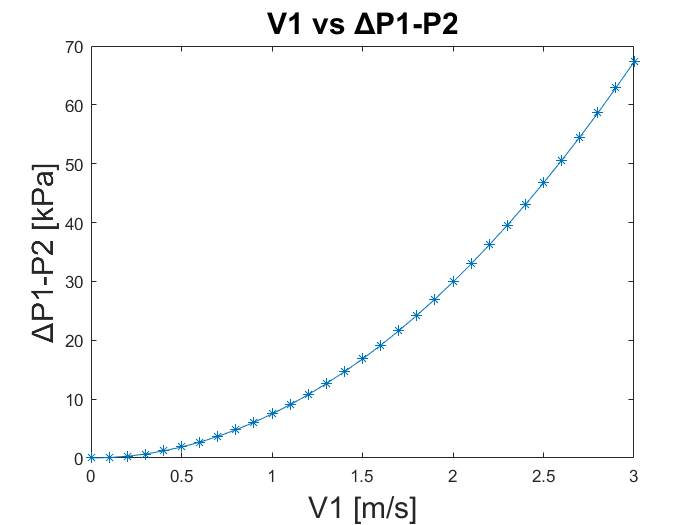

plot(v_,-DP_calc/1000,'*-')
title("V1 vs ΔP1-P2","FontSize",18)
xlabel("V1 [m/s]","FontSize",18)
ylabel("ΔP1-P2 [kPa]","FontSize",18)


v_10 = 0:0.1:10;

DP_calc_10 = -double(subs(DP_,v1,v_10))

DP_calc_10 = 	1.0e+05 *

         0    0.0007    0.0030    0.0067    0.0120    0.0187    0.0269    0.0366    0.0479    0.0606    0.0748    0.0905    0.1077    0.1264    0.1466    0.1682    0.1914    0.2161    0.2423    0.2699    0.2991    0.3298    0.3619    0.3956    0.4307    0.4673    0.5055    0.5451    0.5862    0.6289    0.6730    0.7186    0.7657    0.8143    0.8644    0.9160    0.9691    1.0237    1.0798    1.1373    1.1964    1.2570    1.3190    1.3826    1.4476    1.5142    1.5822    1.6518    1.7228    1.7953


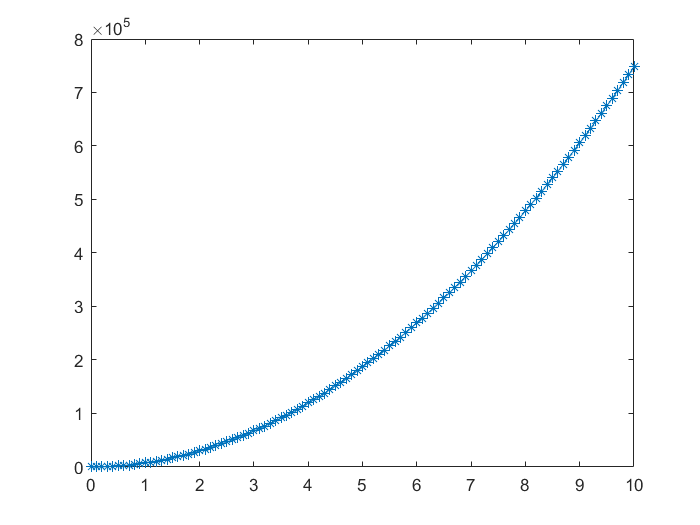

plot(v_10,DP_calc_10,'*-')

## regressione

[P,G]=fit(DP_calc',v_','poly1')

P =      Linear model Poly1:
     P(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -4.163e-05  (-4.584e-05, -3.742e-05)
       p2 =      0.5506  (0.4208, 0.6805)

G = struct with fields:
           sse: 1.6417
       rsquare: 0.9338
           dfe: 29
    adjrsquare: 0.9315
          rmse: 0.2379


V_est=DP_calc*P.p1+P.p2

$$V\_est = \left(\begin{array}{ccccccccccccccccccccccccccccccc} \frac{87}{158} & \frac{32278778072586189158181}{58291711272922183106560} & \frac{8205777056395224299301}{14572927818230545776640} & \frac{33730325147238743928909}{58291711272922183106560} & \frac{2187526802347483084581}{3643231954557636444160} & \frac{7326683859308770694073}{11658342254584436621312} & \frac{9657324131047779070029}{14572927818230545776640} & \frac{40988060520501517782549}{58291711272922183106560} & \frac{682964238835547780901}{910807988639409111040} & \frac{46794248819111736865461}{58291711272922183106560} & \frac{2512083656070577722297}{2914585563646109155328} & \frac{54051984192374510719101}{58291711272922183106560} & \frac{3639073877000037855309}{3643231954557636444160} & \frac{62761266640289839343469}{58291711272922183106560} & \frac{16915059504310552923669}{14572927818230545776640} & \frac{14584419232571544547713}{11658342254584436621312} & \frac{306823597957563954981}{227701997159852277760} & \frac{84534472760078160904389}{58291711272922183106560} & \frac{22721247802920772006581}{14572927818230545776640} & \frac{97598396431951153840941}{58291711272922183106560} & \frac{1308433605261029479353}{728646390911527288832} & \frac{112113867178476701548221}{58291711272922183106560} & \frac{29978983176183545860221}{14572927818230545776640} & \frac{128080884999654804026229}{58291711272922183106560} & \frac{2134511313488102551629}{910807988639409111040} & \frac{29099889979097092254993}{11658342254584436621312} & \frac{38688265624098874484589}{14572927818230545776640} & \frac{164369561865968673294429}{58291711272922183106560} & \frac{10896809250262811708949}{3643231954557636444160} & \frac{184691220911104440084621}{58291711272922183106560} & \frac{9769819029333351575937}{2914585563646109155328} \end{array}\right)$$

Rq=1-norm(v_-V_est)^2/norm(v_-mean(V_est))^2

$$Rq = \frac{2538394889241046531383180022389359165719722576}{2718338882500578496607898783976549479605886905}$$



[P_end,G]=fit([DP_calc(1) DP_calc(end)]',[v_(1) v_(end)]','poly1')

P_end =      Linear model Poly1:
     P_end(x) = p1*x + p2
     Coefficients:
       p1 =  -4.458e-05
       p2 =           0

G = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


V_end=double(DP_calc*P_end.p1+P_end.p2)

V_end =          0    0.0033    0.0133    0.0300    0.0533    0.0833    0.1200    0.1633    0.2133    0.2700    0.3333    0.4033    0.4800    0.5633    0.6533    0.7500    0.8533    0.9633    1.0800    1.2033    1.3333    1.4700    1.6133    1.7633    1.9200    2.0833    2.2533    2.4300    2.6133    2.8033    3.0000


Rq=1-norm(v_-V_end)^2/norm(v_-mean(V_end))^2

Rq = 0.7191

err_lin_end=double(max(abs(v_-V_end))/v_(end))*100

err_lin_end = 25

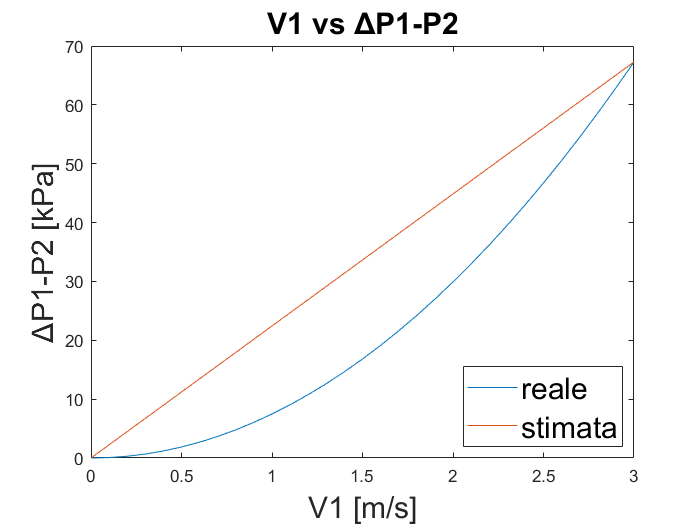

plot(v_,-DP_calc/1e3,V_end,-DP_calc/1e3)
title("V1 vs ΔP1-P2","FontSize",18)
xlabel("V1 [m/s]","FontSize",18)
ylabel("ΔP1-P2 [kPa]","FontSize",18)
legend('reale','stimata',"FontSize",18,'Location','best')

## Scelta sensore

ris=5e-4;%m/s
V=0:ris:10;
DP=-double(subs(DP_,v1,V));
ris=min(diff(DP))

ris = 0.0019

Pmax=max(DP)

Pmax = 747750

# ESERCIZIO 2

clear all
syms Rz PT100 Vout Rg
PT100_20=107.79;
PT100_150=157.31;
Rf=10;
Iref=200e-6

Iref = 2.0000e-04

G=5+200e3/Rg

$$G = \frac{200000}{\mathrm{Rg}}+5$$

## Punto 1

Vout=(Iref*(PT100)-Iref*(Rz))*G;
Vout_0=subs(Vout,PT100,PT100_20)==0

$$Vout\_0 = -\left(\frac{\mathrm{Rz}}{5000}-\frac{10779}{500000}\right)\,\left(\frac{200000}{\mathrm{Rg}}+5\right)=0$$

Vout_5=subs(Vout,PT100,PT100_150)==5

$$Vout\_5 = -\left(\frac{\mathrm{Rz}}{5000}-\frac{15731}{500000}\right)\,\left(\frac{200000}{\mathrm{Rg}}+5\right)=5$$

sol=solve([Vout_5;Vout_0]);

## Punto 2

Rg_id=double(sol.Rg)

Rg_id = 400.1228

Rz_id=double(sol.Rz)

Rz_id = 107.7900

Vout_id=subs(Vout,[Rg Rz],[Rg_id Rz_id])

$$Vout\_id = \frac{710726476802895881\,{\mathrm{PT}}_{100}}{7039035026255881000}-\frac{7660920693458414701299}{703903502625588100000}$$

PT100_=[107.79 108.18 108.57 108.96 109.35 109.73 110.12 110.51 110.90 111.28 ...
    111.67 112.06 112.45 112.83 113.22 113.61 113.99 114.38 114.77 115.15 ...
    115.54 115.93 116.31 116.70 117.08 117.47 117.85 118.24 118.62 119.01 ...
    119.40 119.78 120.16 120.55 120.93 121.32 121.70 122.09 122.47 122.86 ...
    123.24 123.62 124.01 124.39 124.77 125.16 125.54 125.92 126.31 126.69 ...
    127.07 127.45 127.84 128.22 128.60 128.98 129.37 129.75 130.13 130.51 ...
    130.89 131.27 131.66 132.04 132.42 132.80 133.18 133.56 133.94 134.32 ...
    134.70 135.08 135.46 135.84 136.22 136.60 136.98 137.36 137.74 138.12 ...
    138.50 138.88 139.26 139.64 140.02 140.39 140.77 141.15 141.53 141.91 ...
    142.29 142.66 143.04 143.42 143.80 144.17 144.55 144.93 145.31 145.68 ...
    146.06 146.44 146.81 147.19 147.57 147.94 148.32 148.70 149.07 149.45 ...
    149.82 150.20 150.57 150.95 151.33 151.70 152.08 152.45 152.83 153.20 ...
    153.58 153.95 154.32 154.70 155.07 155.45 155.82 156.19 156.57 156.94 ...
    157.31]

PT100_ =   107.7900  108.1800  108.5700  108.9600  109.3500  109.7300  110.1200  110.5100  110.9000  111.2800  111.6700  112.0600  112.4500  112.8300  113.2200  113.6100  113.9900  114.3800  114.7700  115.1500  115.5400  115.9300  116.3100  116.7000  117.0800  117.4700  117.8500  118.2400  118.6200  119.0100  119.4000  119.7800  120.1600  120.5500  120.9300  121.3200  121.7000  122.0900  122.4700  122.8600  123.2400  123.6200  124.0100  124.3900  124.7700  125.1600  125.5400  125.9200  126.3100  126.6900


## Punto 3

Vout_id=double(subs(Vout_id,PT100,PT100_))

Vout_id =          0    0.0394    0.0788    0.1181    0.1575    0.1959    0.2353    0.2746    0.3140    0.3524    0.3918    0.4311    0.4705    0.5089    0.5483    0.5876    0.6260    0.6654    0.7048    0.7431    0.7825    0.8219    0.8603    0.8996    0.9380    0.9774    1.0158    1.0551    1.0935    1.1329    1.1723    1.2106    1.2490    1.2884    1.3267    1.3661    1.4045    1.4439    1.4822    1.5216    1.5600    1.5983    1.6377    1.6761    1.7145    1.7538    1.7922    1.8306    1.8700    1.9083


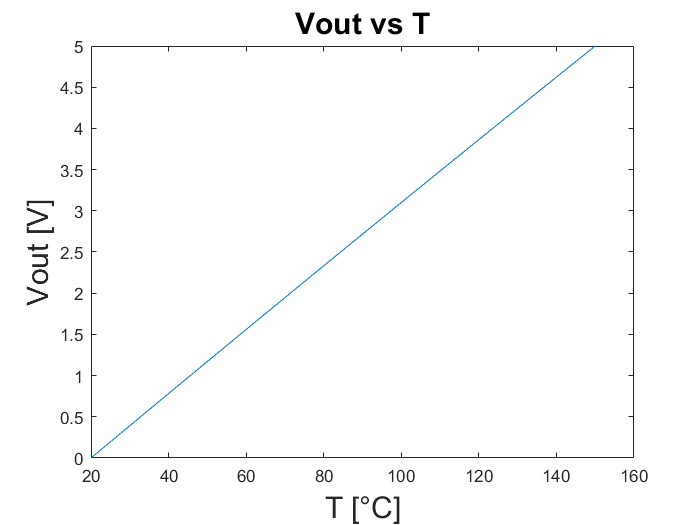

T_=[20:150];
plot(T_,Vout_id)
title("Vout vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vout [V]","FontSize",18)

% [P_BSFT,G_BSFT]=fit(Vout_id',T_','poly1')
% T_est_BFST=Vout_id*P_BSFT.p1+P_BSFT.p2;
% err_lin_BSFT=max(abs(T_-T_est_BFST))/T_(end)*100

## Valori reali

Rz_real=110.8

Rz_real = 110.8000

Rg_real=409

Rg_real = 409

Vout_real=subs(Vout,[Rg Rz],[Rg_real Rz_real])

$$Vout\_real = \frac{40409\,{\mathrm{PT}}_{100}}{409000}-\frac{11193293}{1022500}$$

% Vout_real=double(subs(Vout_real,PT100,PT100_))
PT100min=108.8

PT100min = 108.8000

PT100max=160.3

PT100max = 160.3000

Vout_real_=double(subs(Vout_real,PT100,PT100min))

Vout_real_ = -0.1976

Vout_real=double(subs(Vout_real,PT100,PT100max))

Vout_real = 4.8906

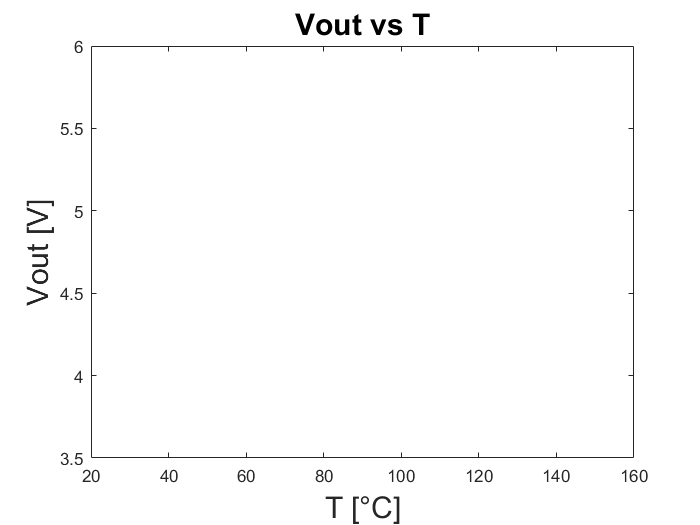

T_=[20:150];
plot(T_,Vout_real)
title("Vout vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vout [V]","FontSize",18)

% [P_BSFT,G_BSFT]=fit(Vout_real',T_','poly1')
% T_est_BFST=Vout_real*P_BSFT.p1+P_BSFT.p2;
% err_lin_BSFT=max(abs(T_-T_est_BFST))/T_(end)*100
T_reale=[109.0 115.2 122.3 129.2 133.4 142.0 149.4 154.4 160.0;
        20 35.0 58.6 70.2 83.3 101.8 129.0 142.0 150]

T_reale =   109.0000  115.2000  122.3000  129.2000  133.4000  142.0000  149.4000  154.4000  160.0000
   20.0000   35.0000   58.6000   70.2000   83.3000  101.8000  129.0000  142.0000  150.0000


% Vp=0.023
% Vm=0.022
% rf=11
